# Sample place field plots, and the checking the stroboscopic effect

In the paper, figure 1b shows an example place field, plotting all non-zero activities in the convolved trace according to where on the track that activity came from. The following plot reproduces it:

The standard deviation of activity per bin is: 1.124398 +- 0.465460 (std)


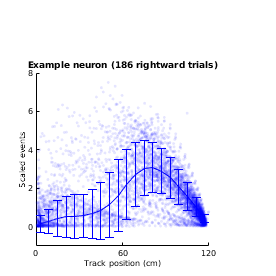

plot_example_pf('Mouse2022', 326);

## Why do we see seashell/stroboscopic effects?

In this section, I will reproduce this visual effect with synthetic data that mimics how we plotted figure 1b.

Consider the following convolution kernel, analogous to our alpha function:

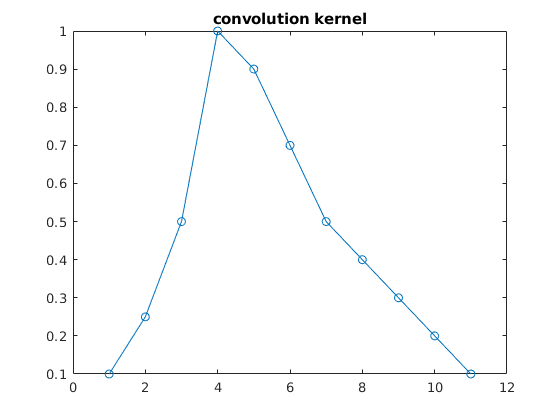

kernel = [0.1 0.25 0.5 1 0.9 0.7 0.5 0.4 0.3 0.2 0.1];
figure; plot(kernel, '-o'); title 'convolution kernel'

Now consider a time-like variable *theta*, that is sampled at an arbitrary irrational sampling rate (to avoid periodicity).

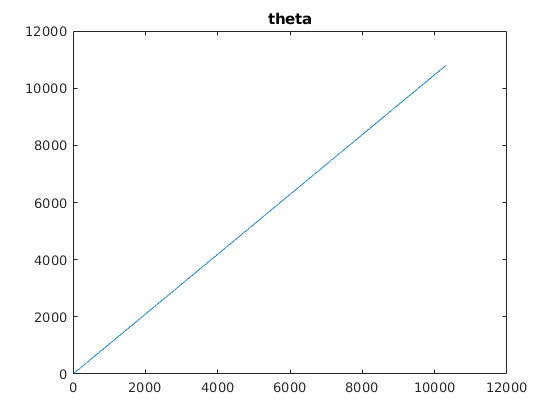

theta = 0:pi/3:360*30;
figure; plot(theta); title theta

Let *p* be analogous to the mouse position on the track, and a periodic function of *theta*:

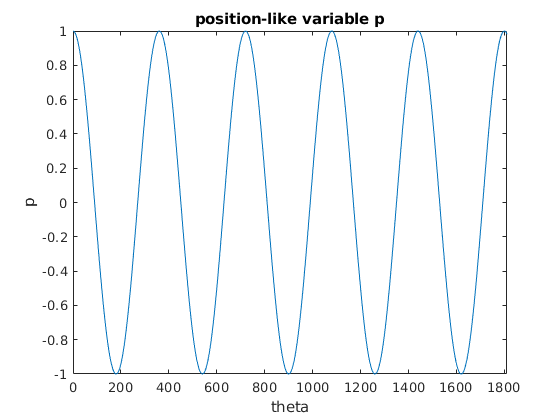

p = cosd(theta);
figure; plot(theta, p); title 'position-like variable p'; xlabel theta; ylabel p
xlim([0 1811]);

Let *v* represent a very simple receptive field that is on if 0 > *p* > 0.25 and off otherwise.

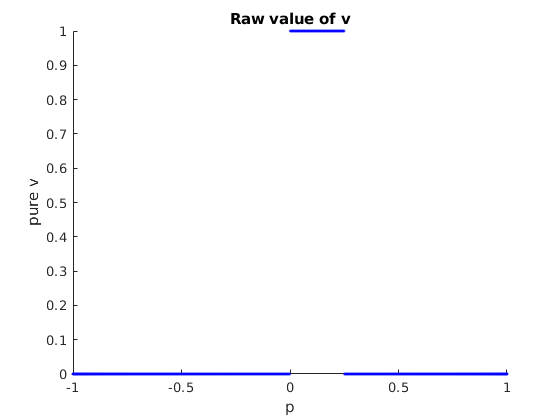

v = p > 0 & p < 0.25;
figure; scatter(p, v, 5, 'b', 'filled'); xlabel p; ylabel 'pure v'; title 'Raw value of v'
alpha(0.1);

Now corrupt *v* with some gaussian measurement noise:

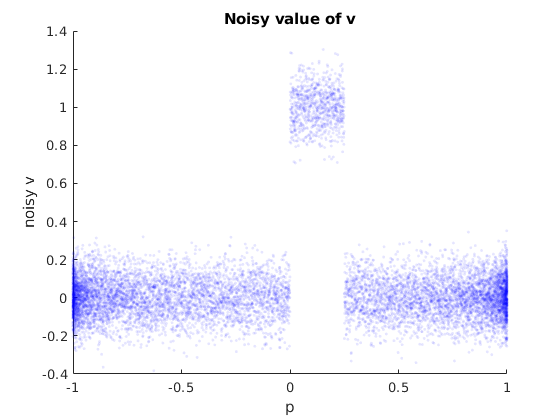

v = v + randn(size(v)).*0.1;
figure; scatter(p, v, 5, 'b', 'filled'); xlabel p; ylabel 'noisy v'; title 'Noisy value of v'
alpha(0.1);

So far, there is no seashell/stroboscopic effect.

Finally, as we do with our data, convolve *v* with the convolution kernel along the time-like variable *theta*. At the same time, select only the positive velocity frames based on the change in *p*.

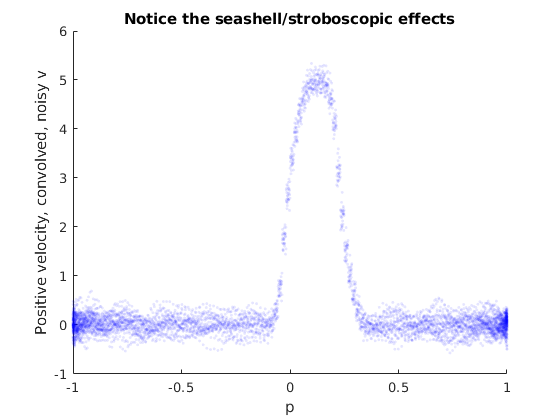

v = conv(v, kernel, 'same');

flt = [false, diff(p) > 0];
p = p(flt);
v = v(flt);
figure;
scatter(p,v, 5, 'b', 'filled');
alpha(0.1);
xlabel 'p'; ylabel 'Positive velocity, convolved, noisy v'; title 'Notice the seashell/stroboscopic effects'

This confirms that even in random data the effect shows up, and it is entirely a consequence of the convolution kernel.

Now what happens if we add random jitter to the x-axis of the plot?

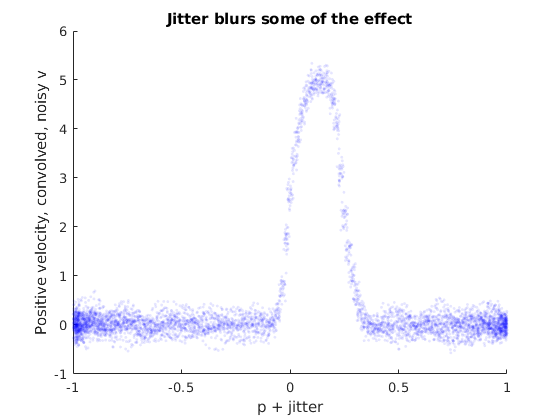

figure;
scatter(p + 2e-2*rand(size(p)), v, 5, 'b', 'filled'); xlim([-1 1]);
alpha(0.1);
xlabel 'p + jitter'; ylabel 'Positive velocity, convolved, noisy v'; title 'Jitter blurs some of the effect'

Here is the original 1b, with jitter added:

plot_example_pf('Mouse2022', 326, 2);

The standard deviation of activity per bin is: 1.124398 +- 0.465460 (std)


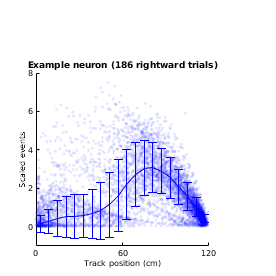

Utils.printto('events_figs/rasters', 'one_cell_variability_nobins_errbars_jitter.pdf');

With even more jitter:

plot_example_pf('Mouse2022', 326, 4);

The standard deviation of activity per bin is: 1.124398 +- 0.465460 (std)


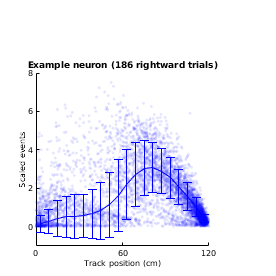

Utils.printto('events_figs/rasters', 'one_cell_variability_nobins_errbars_more_jitter.pdf');

plot_example_pf('Mouse2022', 326, 8);

The standard deviation of activity per bin is: 1.124398 +- 0.465460 (std)


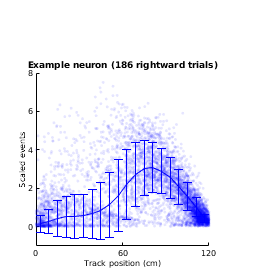

Utils.printto('events_figs/rasters', 'one_cell_variability_nobins_errbars_moremore_jitter.pdf');

We can check what other neurons from the same mouse look like (without jitter): (Mouse2022, cells 26, 103, 388)

Checking cell 26


The standard deviation of activity per bin is: 0.542724 +- 0.359040 (std)


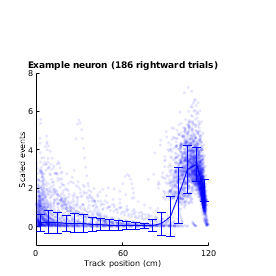

Checking cell 103


The standard deviation of activity per bin is: 1.043739 +- 0.501574 (std)


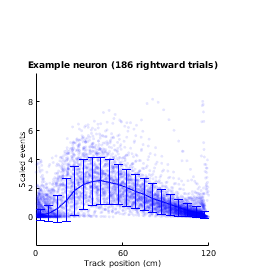

Checking cell 388


The standard deviation of activity per bin is: 1.308871 +- 0.706944 (std)


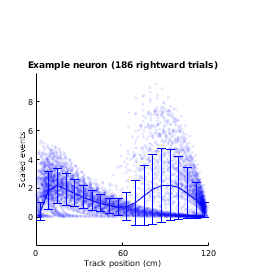

idxs = [26 103 388];
for i = 1:numel(idxs)
    fprintf('Checking cell %d\n', idxs(i))
    plot_example_pf('Mouse2022', idxs(i));    
end

Checking from another mouse: Mouse2024 (cells 208, 102, 269, 50, 238)

Checking cell 208


The standard deviation of activity per bin is: 0.804962 +- 0.639213 (std)


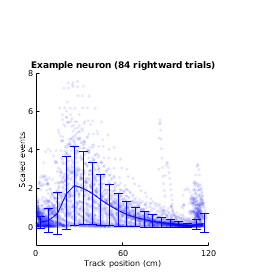

Checking cell 102


The standard deviation of activity per bin is: 1.495438 +- 0.687464 (std)


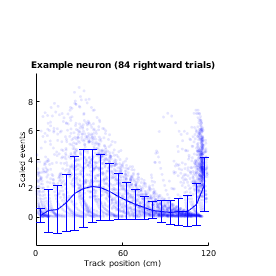

Checking cell 269


The standard deviation of activity per bin is: 0.661913 +- 0.767282 (std)


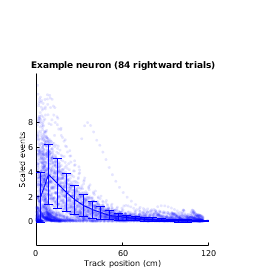

Checking cell 50


The standard deviation of activity per bin is: 0.844319 +- 0.652182 (std)


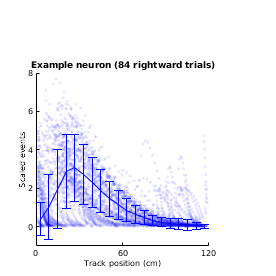

Checking cell 238


The standard deviation of activity per bin is: 1.359637 +- 1.006482 (std)


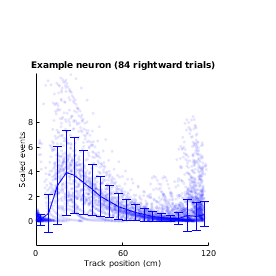

idxs = [208 102 269 50 238];
for i = 1:numel(idxs)
    fprintf('Checking cell %d\n', idxs(i))
    plot_example_pf('Mouse2024', idxs(i));    
end

Checking in one more mouse: Mouse2028, cells: [256, 74, 111, 187, 184, 62]

Checking cell 256


The standard deviation of activity per bin is: 0.935544 +- 0.817620 (std)


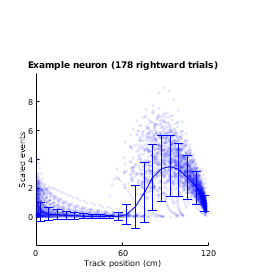

Checking cell 74


The standard deviation of activity per bin is: 1.127784 +- 0.616450 (std)


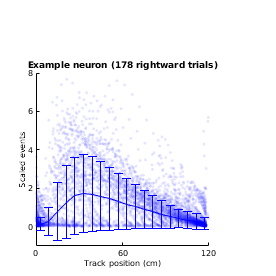

Checking cell 111


The standard deviation of activity per bin is: 1.198647 +- 0.514663 (std)


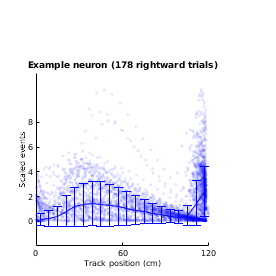

Checking cell 187


The standard deviation of activity per bin is: 0.778457 +- 0.365153 (std)


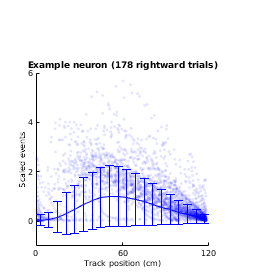

Checking cell 184


The standard deviation of activity per bin is: 0.732849 +- 0.382966 (std)


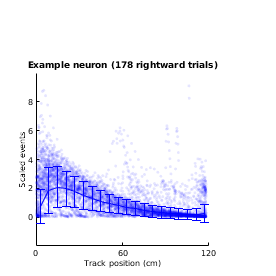

Checking cell 62


The standard deviation of activity per bin is: 0.809378 +- 0.414696 (std)


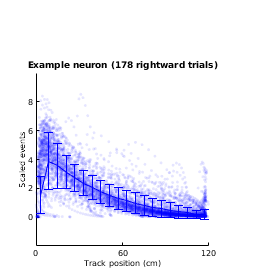

idxs = [256 74 111 187 184 62];
for i = 1:numel(idxs)
    fprintf('Checking cell %d\n', idxs(i))
    plot_example_pf('Mouse2028', idxs(i));    
end

For the sake of aesthetics, we could replace figure 1b with neuron 256 from session Mouse-2028-20150327_105544, if the original is not a great representative:

plot_example_pf('Mouse2028', 256);

The standard deviation of activity per bin is: 0.935544 +- 0.817620 (std)


Utils.printto('events_figs/rasters', 'one_cell_variability_nobins_errbars_alternative.pdf');

And the previous plot with jitter:

plot_example_pf('Mouse2028', 256, 2);

The standard deviation of activity per bin is: 0.935544 +- 0.817620 (std)


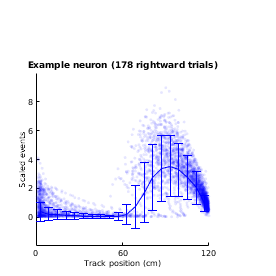

Utils.printto('events_figs/rasters', 'one_cell_variability_nobins_errbars_alternative_jitter.pdf');

function plot_example_pf(mouse, ix, use_jitter)
if ~exist('use_jitter', 'var')
    use_jitter = false;
end
d = SessManager.load_special(mouse, 'events_transients');
S = load(d.source_path);

%ix = 326;
ntype = 'events_transients';
tr = S.tracesEvents.(ntype)(:,ix);

pos = S.tracesEvents.position(:,1);
p_low = prctile(pos,1);
p_high = prctile(pos,99);
pos(pos < p_low) = p_low;
pos(pos > p_high) = p_high;
pos = (pos - p_low) ./ (p_high - p_low) .* 120;
v_filt = diff(pos) > 4/20;

tr = tr(v_filt);
pos = pos(v_filt);
[i,j,v] = find(tr);

p = pos(i);
jitter = use_jitter.*120*0.01*(rand(size(p))-0.5);
figure;
scatter(p+jitter,v, 5, 'b', 'filled');  %%This line plots the blue points
alpha(0.1);
xlim([0 120]);
set(gca, 'XTick', [0 60 120]);
set(gca, 'YTick', [0,2,4,6,8]);
set(gca, 'Box', 'off');
xlabel 'Track position (cm)'
ylabel 'Scaled events'
title(sprintf('Example neuron (%d rightward trials)', sum(d.tr_dir == 1)));

mean_act = mean(d.data_tensor(ix,:,d.tr_dir==1),3);
std_act = std(d.data_tensor(ix,:,d.tr_dir==1),0,3);
bin_centers = 3:6:120;
hold on;
errorbar(bin_centers, mean_act, std_act, 'b');
fprintf('The standard deviation of activity per bin is: %f +- %f (std)\n', mean(std_act), std(std_act));

figure_format([1.8 1.8]);
end